### Gary Larson :

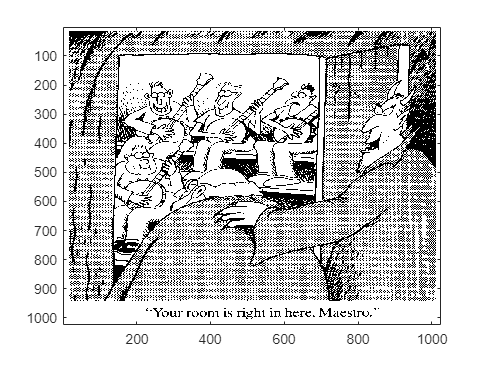

[im,map] = imread('TP_TSI/images/GaryLarson.bmp');

gris = ([0:255]'/255) * [1 1 1];

figure(1);

image(im);

% On force matlab a utiliser des nuances de gris
colormap(gris);

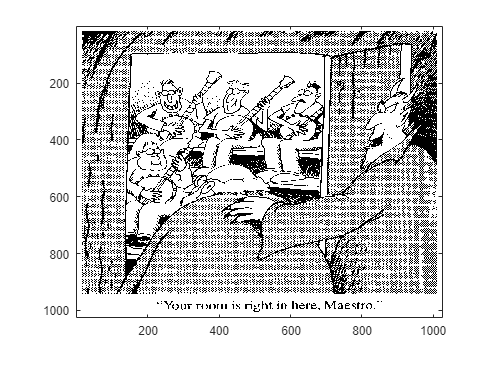


im = double(im);
IM = fft2(im);

% On shift la fréquence 0 au centre
IM = fftshift(IM);

% On passe en logarithmique cuz bro c'est plus logique
logIM = log(abs(IM) + 1);
maxi = max(max(logIM));
mini = min(min(logIM));

% on plot avec des valeurs entre 0 et 255
figure(2);
image((logIM - mini)/(maxi-mini) * 255);
colormap(gris);

### Définition de notre gaussienne :  

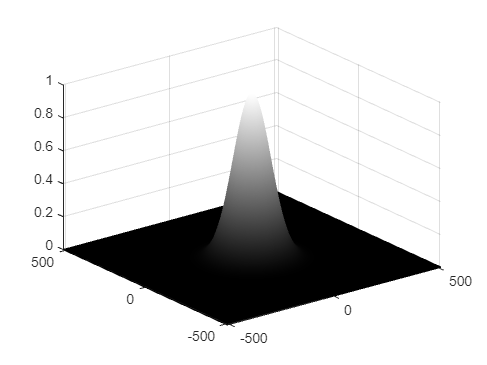

u = linspace(-length(im)/2,length(im)/2,length(im));
v = linspace(-length(im)/2,length(im)/2,length(im));

K = 0.0001;
[u,v] = meshgrid(u,v);

H = exp(-K*(u.^2 + v.^2));


figure(2);
mesh(u,v,H);

### Filtrage de l'image :

filtred_IM = H.*IM;

im_traitee = real(ifft2(fftshift(filtred_IM)));

figure(3);
image(im_traitee);
colormap(gris);

## Restitution de l'image floue

### Visualisation de l'image:

[image_floue , map] = imread("TP_TSI/images/Image_Floue.png");

image(image_floue);
colormap(gris);

### Construire le filtre de reconstitution :

[image_ref , map_ref] = imread("TP_TSI/images/Image_Ref.png");
L = 35;


h = zeros(size(image_ref));
h(length(image_ref)/2 - 5 : length(image_ref)/2 + 5 , length(image_ref)/2 - 17 : length(image_ref)/2 + 17 ) = 1/(11 * 35);

h = double(h);
h = fftshift(h);
H = fft2(h);
H = fftshift(H);

### On construit la transformée de fourirer de l'image de reference

IM_REF = fft2(image_ref);
IM_REF = fftshift(IM_REF);

% Spectre de puissance de l'image de reference
Pir = abs(IM_REF).^2;

### On essaie d'estimer le bruit

% Calculer la convolution entre im_ref et h

D = IM_REF .* H;

d_reconstitue = real(ifft2(fftshift(D)));

b_estimated = d_reconstitue - round(d_reconstitue);

Pb = abs(fftshift(fft2(b_estimated))).^2;

### Implémentation du filtre de Wiener

W = (1./H) .* ((abs(H).^2)./(abs(H).^2 + (Pb./Pir)));

### Filtrage de l'image

IM_FLOUE = fft2(image_floue);
IM_FLOUE = fftshift(IM_FLOUE);

IM_FLOUE_TRAITEE = W .* IM_FLOUE;

im_floue_traitee = real(ifft2(fftshift(IM_FLOUE_TRAITEE)));

logW = log(abs(W) + 1);
mini = min(min(logW));
maxi = max(max(logW));

figure(6);
image((logW-mini/(maxi-mini) * 255));

### Utils:

function eq(im)

    im = double(im);
    IM = fft2(im);
    
    % On shift la fréquence 0 au centre
    IM = fftshift(IM);
    
    % On passe en logarithmique cuz bro c'est plus logique
    logIM = log(abs(IM) + 1);
    maxi = max(max(logIM));
    mini = min(min(logIM));
    
    % on plot avec des valeurs entre 0 et 255
    figure(5);
    image((logIM - mini)/(maxi-mini) * 255);
    colormap(gris);
end

jsp trop de quoi il parlait mais il me semble que c'était pour un L : faut qu'il soit entre 30 et 40 et qu'il soit impair (c'est mieux quand c'est impair apparently)